clear all; close all; clc;
ctr_freq = 1000;
ctr_time = 1/ctr_freq;
max_vel = 1.8/ctr_freq;
endtime = 2;
constime = 0; 
amp = (endtime/2 + constime)*max_vel*ctr_freq/2/2;
[ptraj_pos, ptraj_vel, ptraj_acc] = lspb_core_InertiaID(amp,-amp,endtime,ctr_freq,max_vel);
[ntraj_pos, ntraj_vel, ntraj_acc] = lspb_core_InertiaID(-amp,amp,endtime,ctr_freq,max_vel);
ptraj_vel = ptraj_vel*ctr_freq;
ptraj_acc = ptraj_acc*ctr_freq*ctr_freq;
ntraj_vel = ntraj_vel*ctr_freq;
ntraj_acc = ntraj_acc*ctr_freq*ctr_freq;

csvwrite('JTScalibrationTraj\traj_pos.csv', [ptraj_pos;ntraj_pos]);
csvwrite('JTScalibrationTraj\traj_vel.csv', [ptraj_vel;ntraj_vel])
csvwrite('JTScalibrationTraj\traj_acc.csv', [ptraj_acc;ntraj_acc])

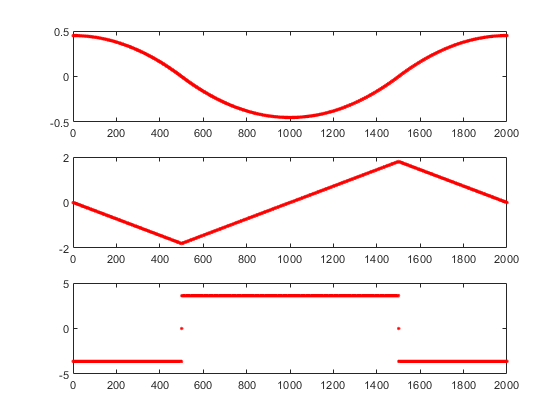

figure
subplot(311)
plot([ptraj_pos;ntraj_pos], 'r.')
subplot(312)
plot([ptraj_vel;ntraj_vel], 'r.')
subplot(313)
plot([ptraj_acc;ntraj_acc], 'r.')